# 期望收益和风险

学习目标:

- `复习数学期望,` `计算资产组合的期望收益率.`

- `复习协方差,` `计算资产组合的风险.`

- `复习夏普比率的概念,` `用`MATLAB`计算夏普比率.`

读入50个股票某2个月的交易数据.

clear;
load price_2m_50stocks.mat;

计算每个股票每天的对数收益率.

rtn = diff(log(price));

作出直方图, 观察每天对数收益率的分布.

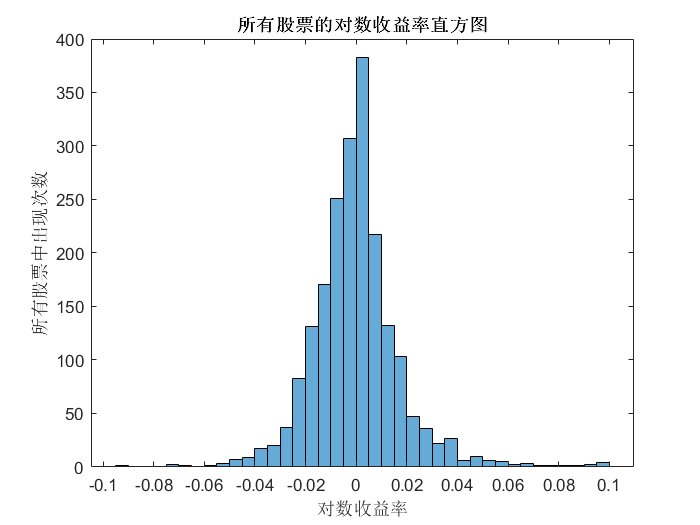

histogram(rtn);
title("所有股票的对数收益率直方图");
xlabel("对数收益率");
ylabel("所有股票中出现次数");

本质上, 资产组合的风险收益是一个**随机变量, **我们需要定义在不同情况下, 随机变量对应的概率分布. 

首先, 我们要确定购买的每个风险资产, 在投资组合中的权重, 暂时我们将其设定为随机.

W = rand(1, 50);
W = W / sum(W);  % 保证权重之和为1.

接着, 计算资产组合的期望收益率.

E_rp = mean(rtn) * W'

E_rp = -2.8950e-04

最后, 计算资产组合的风险, 在这里组合风险用方差表示.

Sig = cov(rtn);
sig_p = (W * Sig * W') .^ 0.5

sig_p = 0.0100

可以看到, 资产组合能够规避单个风险资产的高风险.

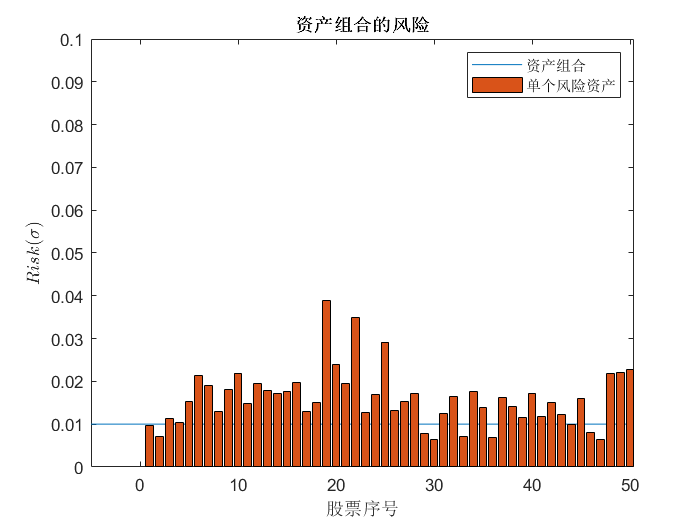

figure;
fplot(sig_p); hold on;
bar(diag(Sig) .^ 0.5);
ylim([0 0.1]);
xlabel("股票序号");
ylabel("$Risk(\sigma)$", "Interpreter","latex");
title("资产组合的风险");
legend(["资产组合", "单个风险资产"])
hold off

计算50个股票的Sharp比率, 假设活期存款的每日利率是0.01%.

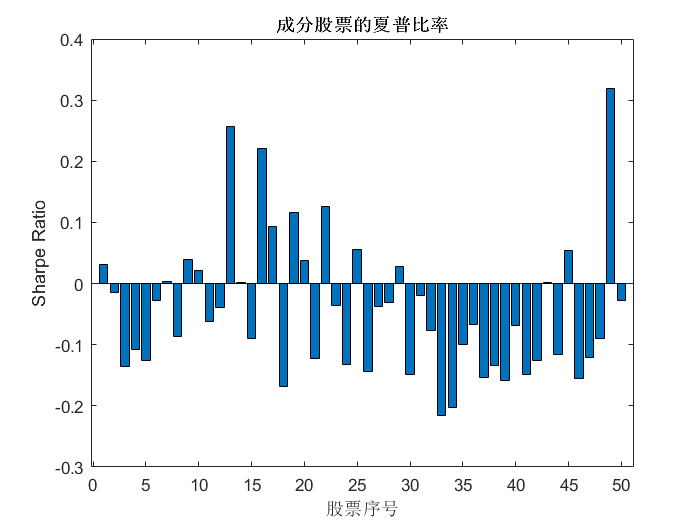

sp = sharpe(rtn, 1e-4);
bar(sp);
xlabel("股票序号");
ylabel("Sharpe Ratio");
title("成分股票的夏普比率");